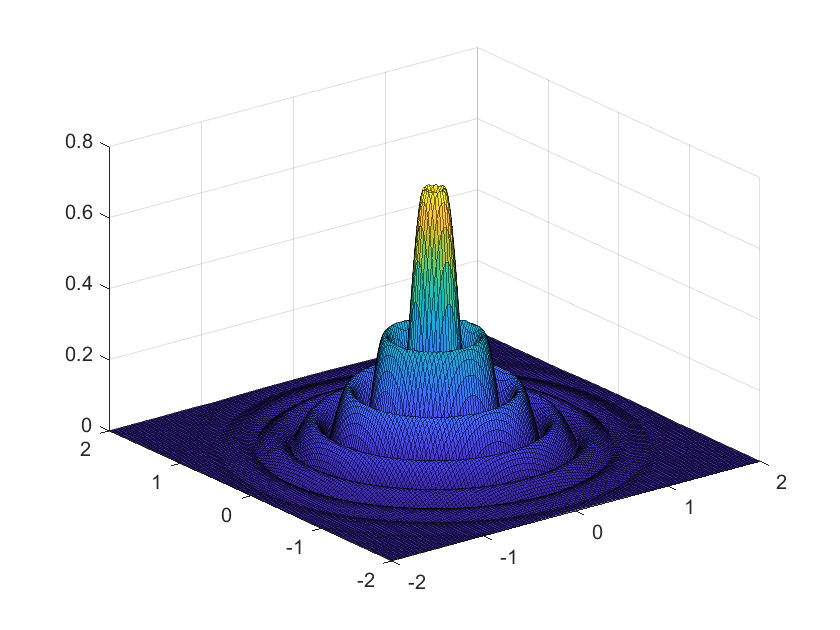

%Non diffractive beam
%==============================================
q = 0.333;
w0 = 10;
x = linspace(-20, 20, 150);
y = x';
r = sqrt(x.^2 + y.^2);
J = abs(besselj(q,r));
E = exp(-(r.^2)/(w0.^2)).*J;
surf(x/w0, y/w0, E, "EdgeAlpha", 0.5)